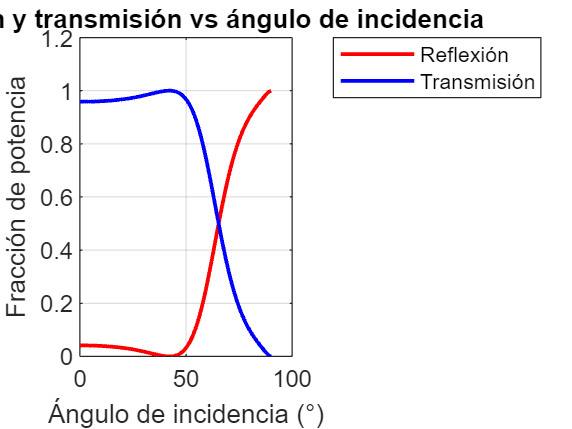

% Parámetros de la capa
Hi = 1;                  % Amplitud incidente
n = [1, 1.5, 1];         % aire -> vidrio -> aire
d = [500e-9,500e-9];            % espesor de la capa
lambda = 600e-9;         % longitud de onda

% Rango de ángulos
thetas = 0:1:90;         % en grados
Rangle = zeros(size(thetas));
Tangle = zeros(size(thetas));

% Calcular reflexión y transmisión para cada ángulo
for k = 1:length(thetas)
    theta_rad = deg2rad(thetas(k));  % convertir a radianes
    [~,~,Pi,Pr,Pt] = inter(Hi, theta_rad, n, d, lambda,false);
    Rangle(k) = Pr/Pi;  % reflexión relativa
    Tangle(k) = Pt/Pi;  % transmisión relativa
end

% Graficar
figure;
plot(thetas, Rangle,'r','LineWidth',1.5);
hold on;
plot(thetas, Tangle,'b','LineWidth',1.5);
xlabel('Ángulo de incidencia (°)');
ylabel('Fracción de potencia');
title('Reflexión y transmisión vs ángulo de incidencia');
grid on;
ylim([0 1.2]);  % margen superior
legend('Reflexión','Transmisión','Location','northeastoutside');